# Segmentation Process

With focus on leaf

## Pulling all bands from 1 unique leaf (interleave method seems best)

%%% ID 980 
%ms1000Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_100050_ID980\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms200Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_100050_ID980\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%%% ID 810 
%ms1000Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200828_104729_ID810\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms200Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200828_104729_ID810\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%%% ID 983
%ms1000Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_095506_ID983\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms200Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_095506_ID983\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%%% ID 949 
ms1000Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_112755_ID949\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0','bsq','ieee-be');
ms200Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_112755_ID949\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%%% ID 982 
%ms1000Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_100532_ID982\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms200Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_100532_ID982\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%%% ID 979
%ms1000Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_101020_ID979\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat',[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms200Cube = multibandread('G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_101020_ID979\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat',[1024,1024,80],'uint16',0,'bsq','ieee-be');

%%% ID 972
%ms1000Cube = multibandread("G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_095137_ID972\leaf_2020_1000ms_80\leaf_2020_1000ms_80_000000\leaf_2020_1000ms_80_000000.dat",[1024,1024,80],'uint16',0','bsq','ieee-be');
%ms200Cube = multibandread("G:\Shared drives\Leaf_cabinet_data\leaf_2020_cabinet_200919_095137_ID972\leaf_2020_200ms_80wl\leaf_2020_200ms_80wl_000000\leaf_2020_200ms_80wl_000000.dat",[1024,1024,80],'uint16',0','bsq','ieee-be');


## All the wavelengths used

wv = [500.0,505.1,510.1,515.2,520.3,525.3,530.4,535.4,540.5,545.6,550.6,555.7,560.8,565.8,570.9,575.9,581.0,586.1,591.1,596.2,601.3,606.3,611.4,616.5,621.5,626.6,631.6,636.7,641.8,646.8,651.9,657.0,662.0,667.1,672.2,677.2,682.3,687.3,692.4,697.5,702.5,707.6,712.7,717.7,722.8,727.8,732.9,738.0,743.0,748.1,753.2,758.2,763.3,768.4,773.4,778.5,783.5,788.6,793.7,798.7,803.8,808.9,813.9,819.0,824.1,829.1,834.2,839.2,844.3,849.4,854.4,859.5,864.6,869.6,874.7,879.7,884.8,889.9,894.9,900.0];

## Interleave 1000ms and 200ms images for purity

interCube(:,:,1:46) = ms200Cube(:,:,1:46);
interCube(:,:,47:80) = ms1000Cube(:,:,47:80);

## Converting into a hypercube (Camera's .hdr file doesn't conform to contructor function, thus extra work)

hCube = hypercube(interCube,wv);

## applying a crop reduction to hypercube data 603x681 (for leaf)

row = 200:802;
col = 100:780;
hCube = cropData(hCube,row,col);

## Create RGB image from cube bands

rgbImgCropped = colorize(hCube);

## Luminance,Alpha,Beta (L*a*b*)

%break rgb image into luminance, red, yellow/blue
segx = rgb2lab(rgbImgCropped);
% clustering over single() precision to reduce noise
%Luminance values ranging from negative 3.402823e38 to positive 3.402823e38
%[-34.0000 : 34.0000]
leafSeg = imsegkmeans(single(segx),2,'NumAttempts',8);



## Display results of leaf clustering

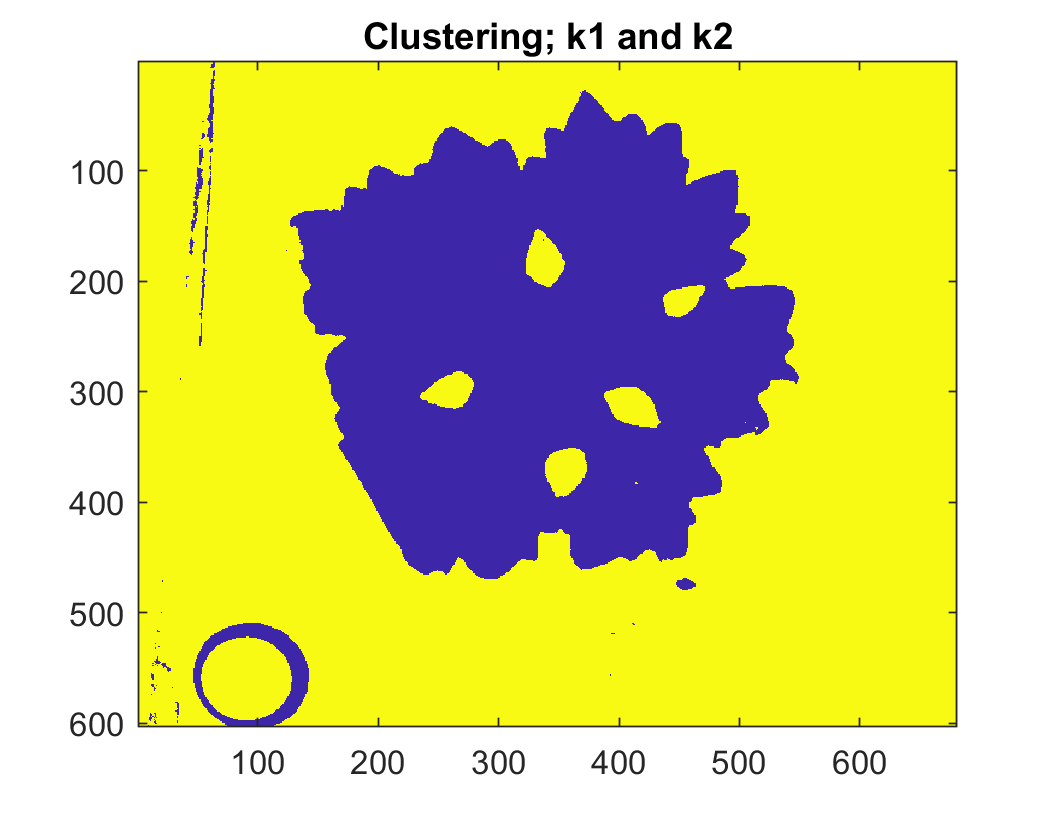

% Cluster index is assigned in ascending order, respective to the largest region area
% currently this is hardcoded for presentation purposes
%leafCluster = 2;
imagesc(leafSeg);
title("Clustering; k1 and k2");

## label the leaf cluster (TODO: create seperate f(x) to customize inner square)

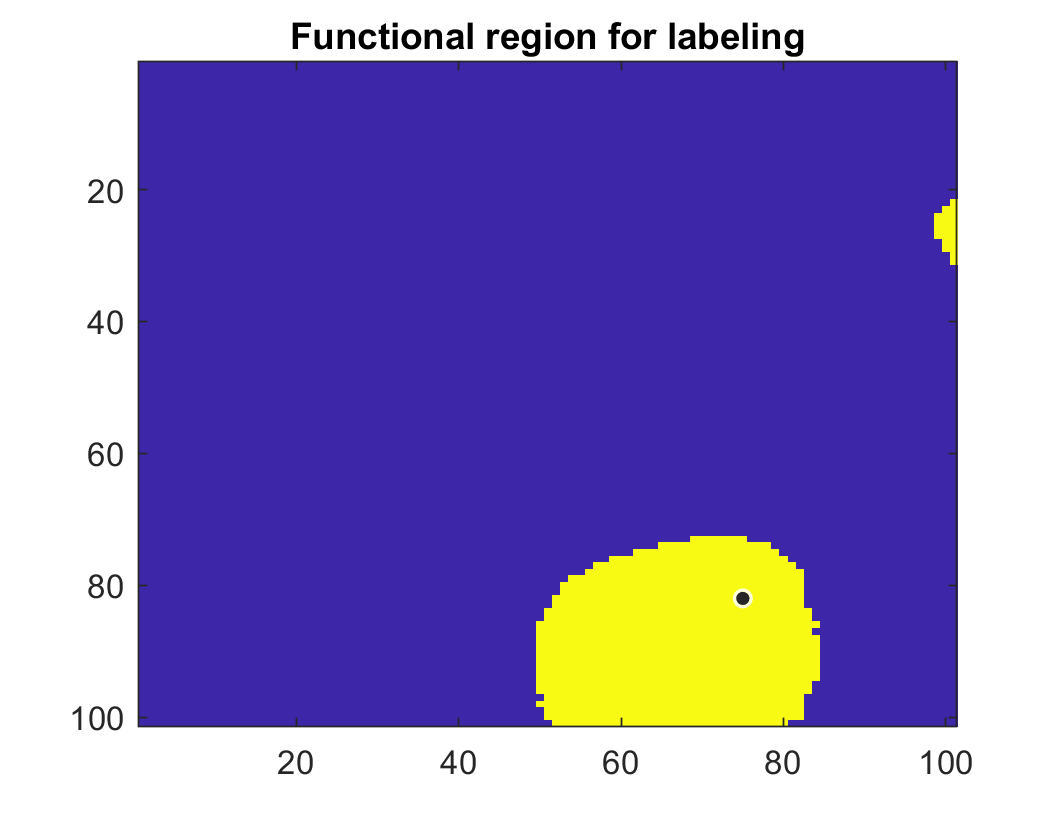

% first gather extent coordinates
%colLimit = length(leafSeg);              %681
%rowLimit = length(leafSeg(:,1));         %603

%croppedLimit
%newColLimit = cast(colLimit * .6,'int16');             %409
%newRowLimit = cast(rowLimit * .6,'int16');             %362

%colOffset = colLimit - newColLimit;                    %272
%rowOffset = rowLimit - newRowLimit;                    %241

%Hard code it for now
rec = [290 279 100 100];                
% apply the crop, label cluster
segFocus = imcrop(leafSeg, rec);
% what the focus region for labeling looks like:
imagesc(segFocus);
title("Functional region for labeling");

leafCluster = mode(segFocus(:));


## Convert to logical representation

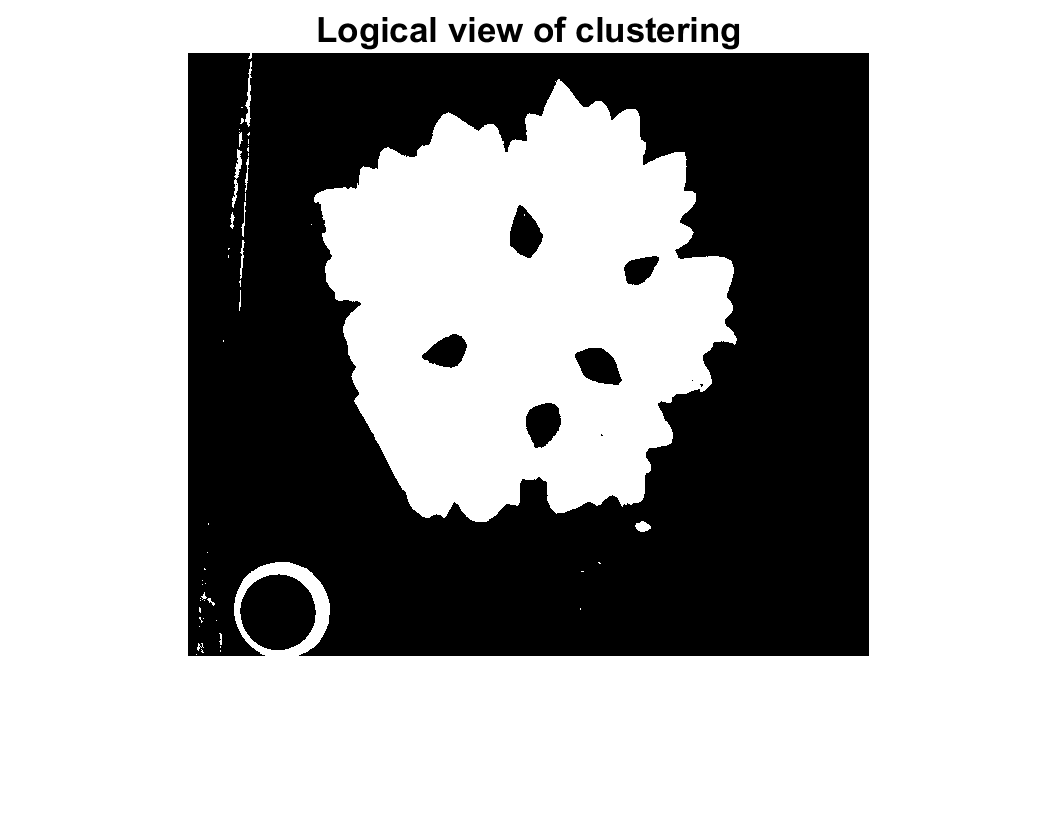

leafSeg = leafSeg == leafCluster;
imshow(leafSeg);
title("Logical view of clustering");

## Grab circle pixel coordinates [entire circle, just the outside] (both values of this function can be used to grab just the area within edges)

% Custom function, depends on 'segCircle.m' to be in scope
[fullCircle,outline] = segCircle(cast(leafSeg,'double'));

## Create a mask with inverted outline

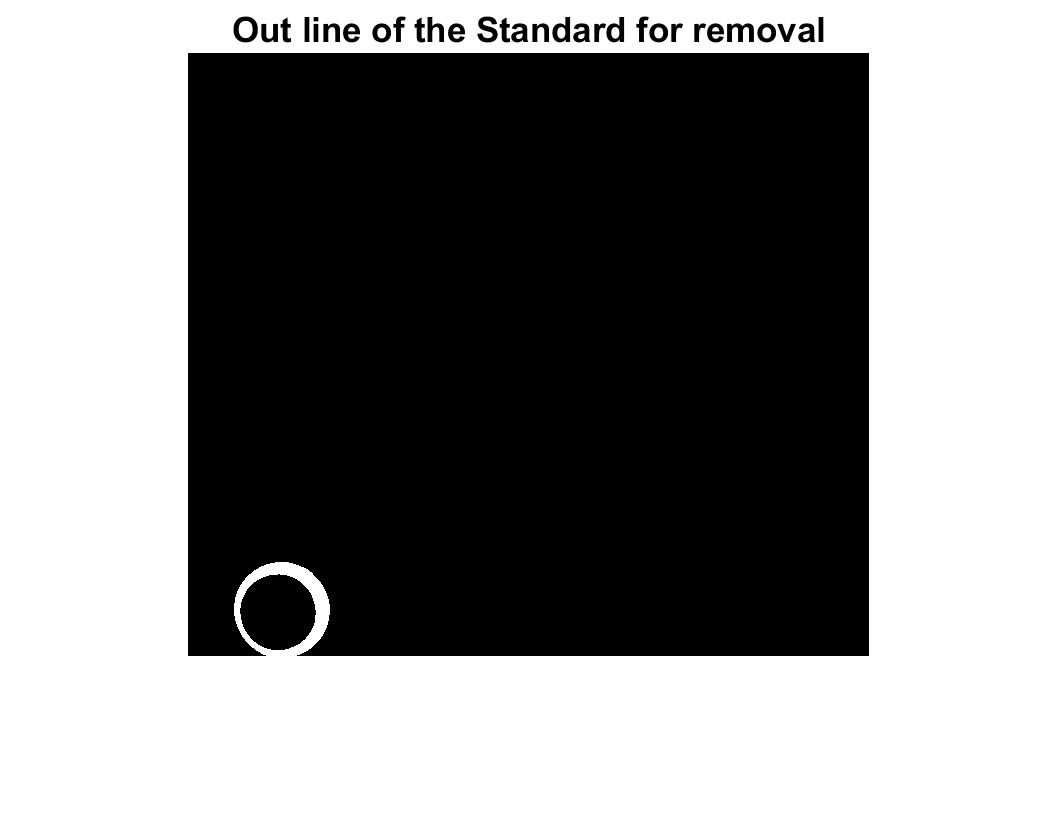

% invert the outline, logically
mask = outline >0;
imshow(mask);
title("Out line of the Standard for removal");

## Subtract inverted mask from image

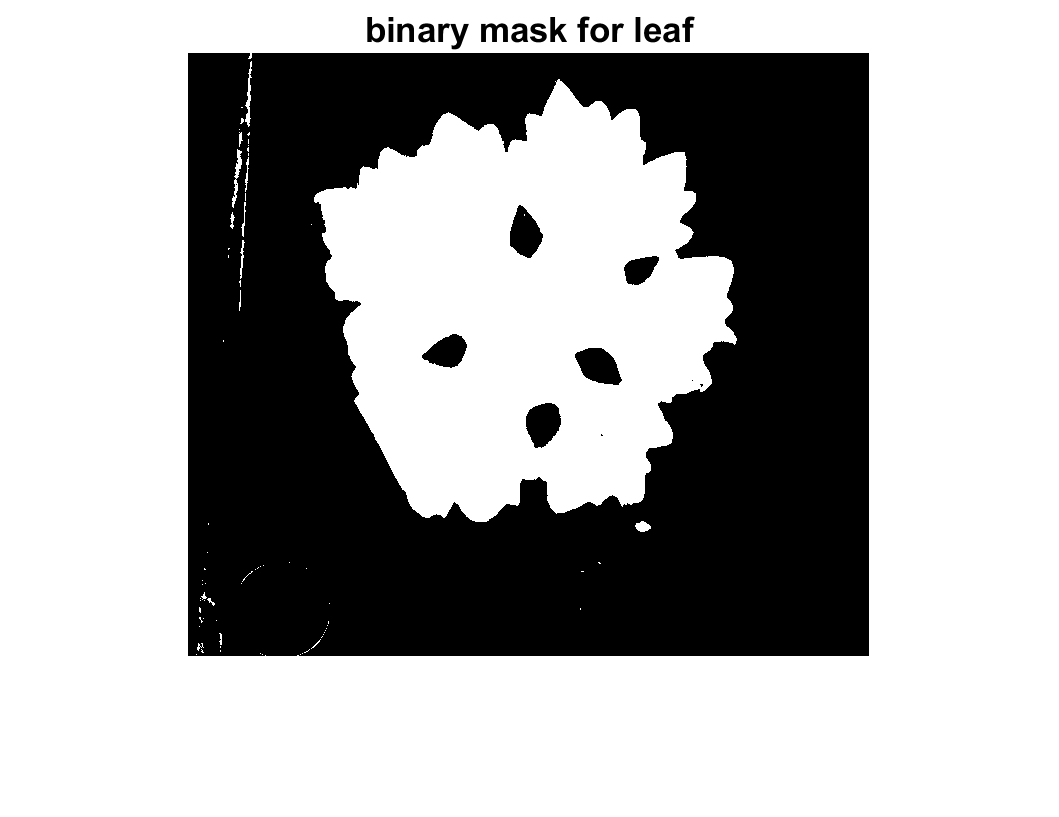

leaf = leafSeg ~= mask;
imshow(leaf);
title("binary mask for leaf");

## Display the leaf with mask applied(USING wv 697.5nm to illustrate mask efficacy)

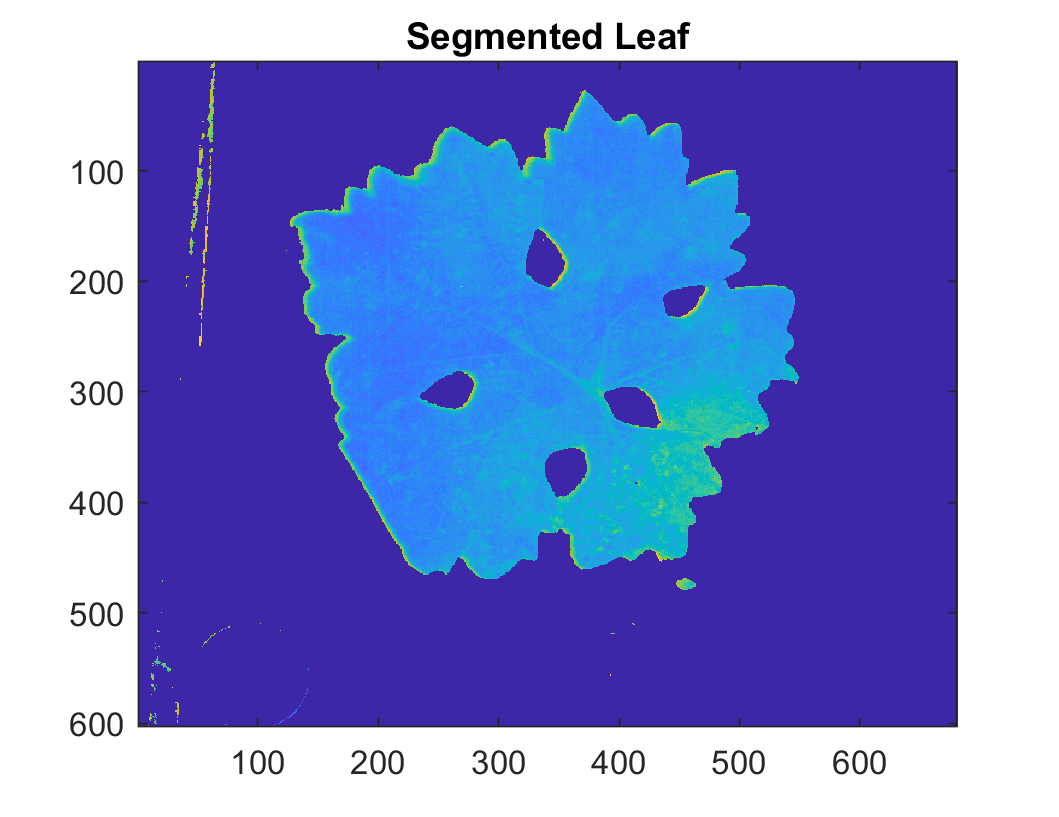

i = hCube.DataCube(:,:,40);
i = i.*leaf;
imagesc(i);
title("Segmented Leaf");